load data_ml.mat
data_ml = data_ml( data_ml.date > datetime(1999,12,31) & ...
                   data_ml.date < datetime(2019,01,01) , : ) ;
data_ml = sortrows(data_ml,["stock_id","date"]) ;

stock_ids = data_ml.stock_id ;
stock_days = groupcounts( data_ml(:,["stock_id","date"]), "stock_id" ) ;
stock_days.Properties.VariableNames{2} = 'nb' ;
head(stock_days)

ans = 8×2 table
    stock_id    nb 
    ________    ___

       1        228
       2        225
       3        228
       4        228
       5        227
       6        227
       7        228
       8        227


stock_ids_short = stock_days(stock_days.nb == max(stock_days.nb) , "stock_id" ) ;

for stock_count = 1 : height(stock_ids_short)

    current_stock = stock_ids_short{stock_count,:} ;
    
    if stock_count == 1

        returns = data_ml( data_ml.stock_id == current_stock, ["date","R1M_Usd"] ) ;
        returns.Properties.VariableNames{stock_count + 1 } = num2str( current_stock ) ; % This does not work in R2019a
        
    else
        
        temp_returns = data_ml( data_ml.stock_id == current_stock, ["date","R1M_Usd"] ) ;
        temp_returns.Properties.VariableNames{2} = num2str( current_stock ) ;
        returns = outerjoin(returns, temp_returns, "keys", "date", "Type","Right","MergeKeys",true) ;
        
    end
    
    
end

%data_ml = sortrows(data_ml,"date")
data_ml.large = data_ml.Mkt_Cap_12M_Usd > median(data_ml.Mkt_Cap_12M_Usd) ;
data_ml.year = year( data_ml.date ) ;
data_ml = sortrows(data_ml, ["year","large"], ["ascend","descend"])

data_ml = 268336×101 table
    stock_id       date       Advt_12M_Usd    Advt_3M_Usd    Advt_6M_Usd    Asset_Turnover    Bb_Yld     Bv     Capex_Ps_Cf    Capex_Sales    Cash_Div_Cf    Cash_Per_Share    Cf_Sales    Debtequity    Div_Yld    Dps     Ebit_Bv    Ebit_Noa    Ebit_Oa    Ebit_Ta    Ebitda_Margin    Eps     Eps_Basic    Eps_Basic_Gr    Eps_Contin_Oper    Eps_Dil     Ev     Ev_Ebitda    Fa_Ci    Fcf     Fcf_Bv    Fcf_Ce    Fcf_Margin

data_summarize = data_ml(:,["year","large", "R1M_Usd"]) ;
test = groupsummary(data_summarize,["year","large"], "mean")

test = 38×4 table
    year    large    GroupCount    mean_R1M_Usd
    ____    _____    __________    ____________

    2000    false       6699          0.034768 
    2000    true        6371          0.015643 
    2001    false       7010          0.032545 
    2001    true        6609         0.0032491 
    2002    false       7034         0.0047216 
    2002    true        6961         -0.012454 
    2003    false       7124          0.045006 
    2003    true        7122          0.029757 
    2004    false       7192          0.012852 
    2004    true        7126         0.0081904 
    2005    false       7200          0.022556 
    2005    true        7132          0.013219 
    2006    false       7199           0.01262 
    2006    true        7150          0.012142 
    2007    false       7176        -0.0032239 
    2007    true        7145 

x = reshape( test.mean_R1M_Usd, 2, 19  )'

x =     0.0348    0.0156
    0.0325    0.0032
    0.0047   -0.0125
    0.0450    0.0298
    0.0129    0.0082
    0.0226    0.0132
    0.0126    0.0121
   -0.0032   -0.0023
   -0.0192   -0.0346
    0.0491    0.0346



%{

% This is intuitive 

yrs = unique( test.year ); 
for i = 1 : numel( yrs ) 
    x(i,:) = test{ test.year == yrs(i), 'mean_R1M_Usd' }' ;
end

%}

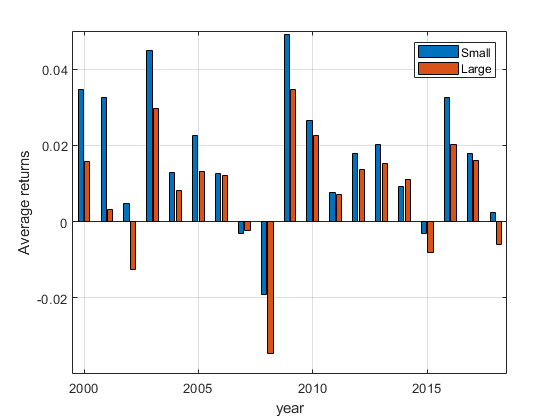

bar(unique(data_summarize.year), x)
grid on
ylim([-0.04  0.05])
yticks([-0.02 : 0.02 : 0.05])
xticks([2000 : 5 : 2018])
xlabel('year')
ylabel('Average returns')
legend({'Small','Large'})

min_date = datetime(1963,07,31) ;
max_date = datetime(2020,05,28) ;
KF_website = 'https://mba.tuck.dartmouth.edu/pages/faculty/ken.french/' ; 
filename = "F-F_Research_Data_5_Factors_2x3_CSV.zip" ;
KF_file  = 'ftp/F-F_Research_Data_5_Factors_2x3_CSV.zip' ;
link= strcat(KF_website,KF_file) ;
websave(filename,link) ;
unzip(filename)

FF_factors = readtable("F-F_Research_Data_5_Factors_2x3.CSV") ;

FF_factors.Properties.VariableNames{1} = 'date' ;
FF_factors.date = datetime( strcat( string(FF_factors.date), "01" ), "Format", "yyyyMMdd" ) + calmonths(1) - caldays(1) ;
FF_factors{:,2:end} = FF_factors{:,2:end} / 100 ;

plot_FF_factors = table2timetable( FF_factors ,"RowTimes", "date" ) ;
plot_FF_factors = retime(plot_FF_factors,"yearly","mean") ; % check values. Not matching 

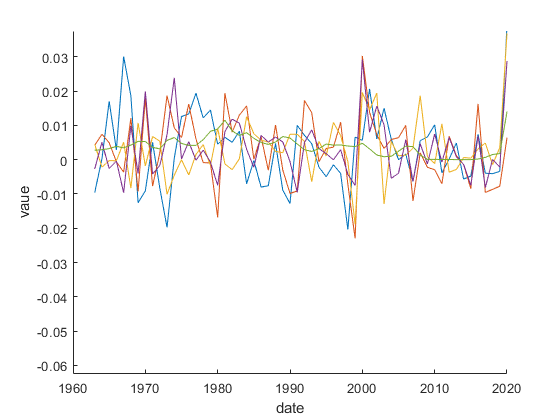

figure ;
hold on ;
for i = 2 : width(plot_FF_factors) 
    plot( year( plot_FF_factors.date ), plot_FF_factors{:,i} ) % verify plot
end
hold off;
xlabel('date')
ylabel('vaue')
xlim([ 1960 2020 ])
ylim([-0.0625 0.0375])